# Habeeb and Brian

clc
clear all

data = load('gdata.mat');
dn = data.dn;
x = data.x;
rhox = data.rhox;

a = 0; b = 1000; n = 100; m = 500;

R = 6.67428e-11; % Newton's gravitational constant
A = 1;
h = 25 - sqrt(A/pi);

dxc = (b-a)/n;

g = @(xc,x) (R*h./((xc - x).^2 + h^2)^(3/2));
xc = [];
for j = 1:n
    xc = [xc a + (dxc/2) + (j-1)*dxc]; %form xc
end
xc;

G = zeros(m,n);
for i = 1:m
    for j = 1:n
        G(i,j) = g(xc(j), x(i)).*dxc;
    end
end

G;

### a. Invert for density perturbations along the pipe transect in kg/m3 using least squares.

ML2 = inv(G'*G)*G'*dn;
min(ML2);
max(ML2);

The magnitude of the least square estimates coincide with those of rhox, hence the estimates approximate rhox. The estimates lies between $$-1.1891*10^{3}$ $ and $1.1185*10^{3}$

### Analyze the resolution in your model parameter estimates.

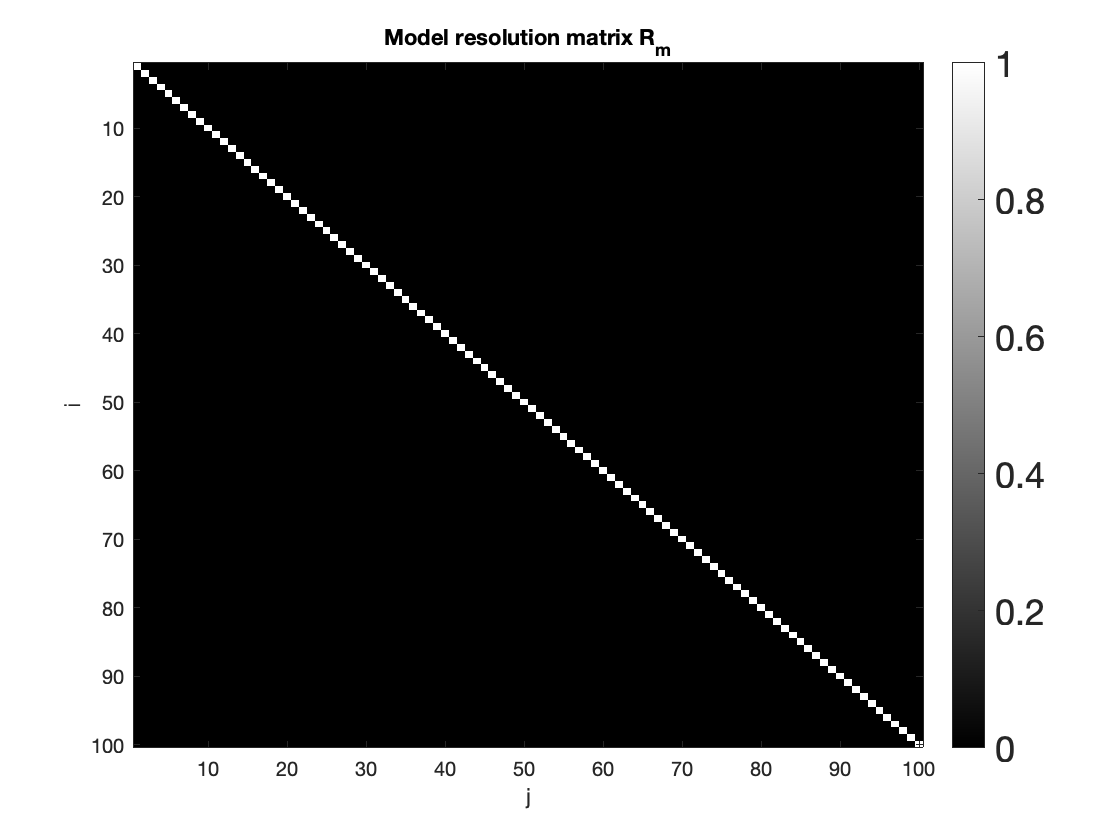

% Get the singular values for the system matrix
[U,S,V] = svd(G);

[m,n] = size(G);

%rank
p=rank(G);

% model resolution matrix
Vp=V(:,1:p);
Rm=Vp*Vp';

figure(1)
clf
colormap('gray')

imagesc(Rm)
set(colorbar,'Fontsize',18);
xlabel('j')
ylabel('i')
title('Model resolution matrix R_{m}')

The model parameter estimates are perfectly resolved, since all the entries on the major diagonal equal to 1 and the rest are zeros.

### b. Invert for density perturbations along the pipe transect in kg/m3 using second order Tikhonov regularization and TGSVD.

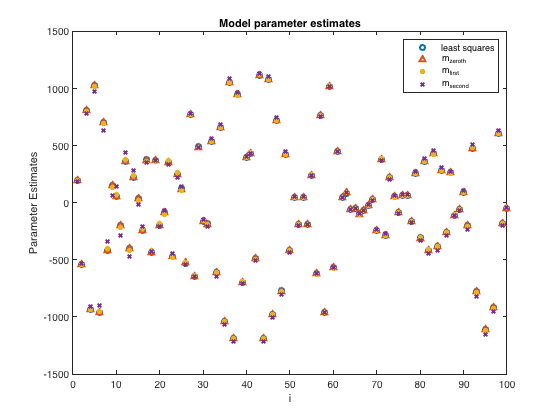

%generate roughening matrices
L1 = get_l_rough(n,1);
L2 = get_l_rough(n,2);

% TGSVD
[U,V,X,S,M] = gsvd(G,eye(n)); Y = (inv(X)');
[U1,V1,X1,S1,M1] = gsvd(G,L1); Y1 = (inv(X1)');
[U2,V2,X2,S2,M2] = gsvd(G,L2); Y2 = (inv(X2)');

% generalized singular values of G and L
lam = @(S) sqrt(diag(S'*S));
mu = @(M) sqrt(diag(M'*M));

k = 0; %m>n
q2 = 100;

Lam = lam(S); Lam1 = lam(S1); Lam2 = lam(S2);

M0 = model_parameters(q2,U,Lam,Y,k,dn,n);
M_1 = model_parameters(q2,U1,Lam1,Y1,k,dn,n);
M_2 = model_parameters(q2,U2,Lam2,Y2,k,dn,n);

figure(2)
clf
plot(ML2,'o','LineWidth',2,"MarkerSize",5); hold on
plot(M0,'^','LineWidth',2,"MarkerSize",5); 
plot(M_1,'*','LineWidth',2,"MarkerSize",5); 
plot(M_2,'x','LineWidth',2,"MarkerSize",5); hold off
legend('least squares','m_{zeroth}','m_{first}','m_{second}')
xlabel('i'); ylabel('Parameter Estimates')
title('Model parameter estimates')

According to the plot above, they  all have almost the same estimates, however the TGSVD solutions depends on the value of q.

### c. Solve the problem using second-order Tikhonov regularization combined with BVLS and a TGSVD analysis.

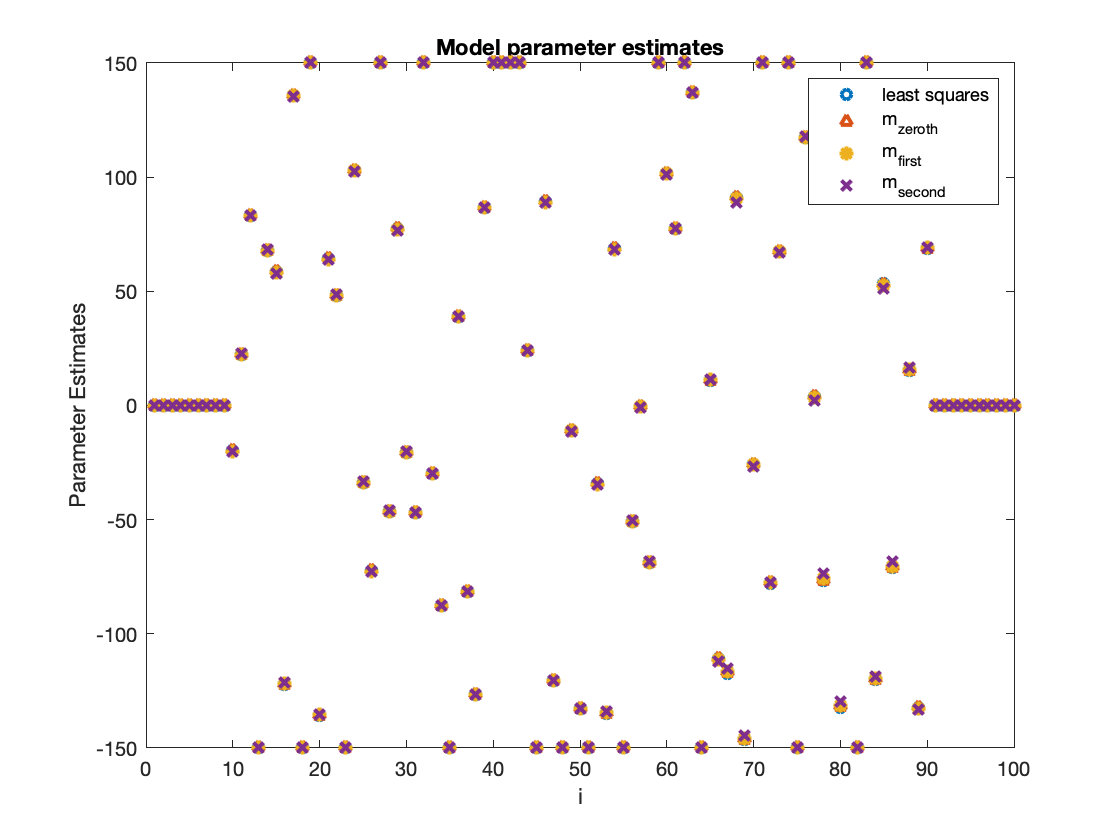

%zeroth order
L = eye(n);

% get the points and solutions for the first and second order TGSVD L-curve
[rho,eta,reg_param,ms]=l_curve_tgsvd(U,dn,X,S,G,L);
[rho1,eta1,reg_param1,m1s]=l_curve_tgsvd(U1,dn,X1,S1,G,L1);
[rho2,eta2,reg_param2,m2s]=l_curve_tgsvd(U2,dn,X2,S2,G,L2);

ireg_corner = 90;
alpha0=rho(ireg_corner);
alpha1=rho1(ireg_corner);
alpha2=rho2(ireg_corner);

alpha = [alpha0 alpha1 alpha2];

%generate lower and upper bounds
l= -150.*ones(n,1);
u= 150.*ones(n,1);

%stack the dn matrices
d0 = [dn; zeros(n,1)];
d1 = [dn; zeros(n-1,1)];
d2 = [dn; zeros(n-2,1)];

%stack the matrices
A = [G; alpha(1)*L];
A1 = [G; alpha(2)*L1];
A2 = [G; alpha(3)*L2];

%find positions of 91 and 899 in m
pos = find(xc < 91); pos_91 = pos(end);
pos = find(xc > 899); pos_899 = pos(1);

%setting bounds for xc
l(1:pos_91) = 0; l(pos_899:end) = 0;
u(1:pos_91) = 0; u(pos_899:end) = 0;

ML2 = bvls(G, dn,l, u);  %least squares
M0 = bvls(A, d0,l, u);   
M1 = bvls(A1, d1,l, u);   
M2 = bvls(A2, d2,l, u);   

figure(3)
clf
plot(ML2,'o','LineWidth',2,"MarkerSize",5); hold on
plot(M0,'^','LineWidth',2,"MarkerSize",5); 
plot(M1,'*','LineWidth',2,"MarkerSize",5); 
plot(M2,'x','LineWidth',2,"MarkerSize",5); hold on
legend('least squares','m_{zeroth}','m_{first}','m_{second}')
xlabel('i'); ylabel('Parameter Estimates')
title('Model parameter estimates')

According to the plot above, they  all have almost the same estimates, however after implementing the bounds, the estimates outside the bounds are negilible (hence made zeros.

### Where are the prominent maxima and minima located?

%minima
find(ML2==min(ML2))';
minima_locations =find(M0==min(M0))'

minima_locations =     13    18    23    35    45    48    51    55    64    75    82


find(M1==min(M1))' ;
find(M2==min(M2))';
%maxima
maxima_locations = find(ML2==max(ML2))'

maxima_locations =     19    27    32    40    41    42    43    59    62    71    74    83


maxima_locations_zeroth =find(M0==max(M0))'

maxima_locations_zeroth =     19    27    32    40    41    42    43    62    71    74    83


find(M1==max(M1))' ;
find(M2==max(M2))';

They all have the same prominent minima and maxima locations except the mxima for the zeroth order solution. 

### Analyze the resolution in your model parameter estimates.

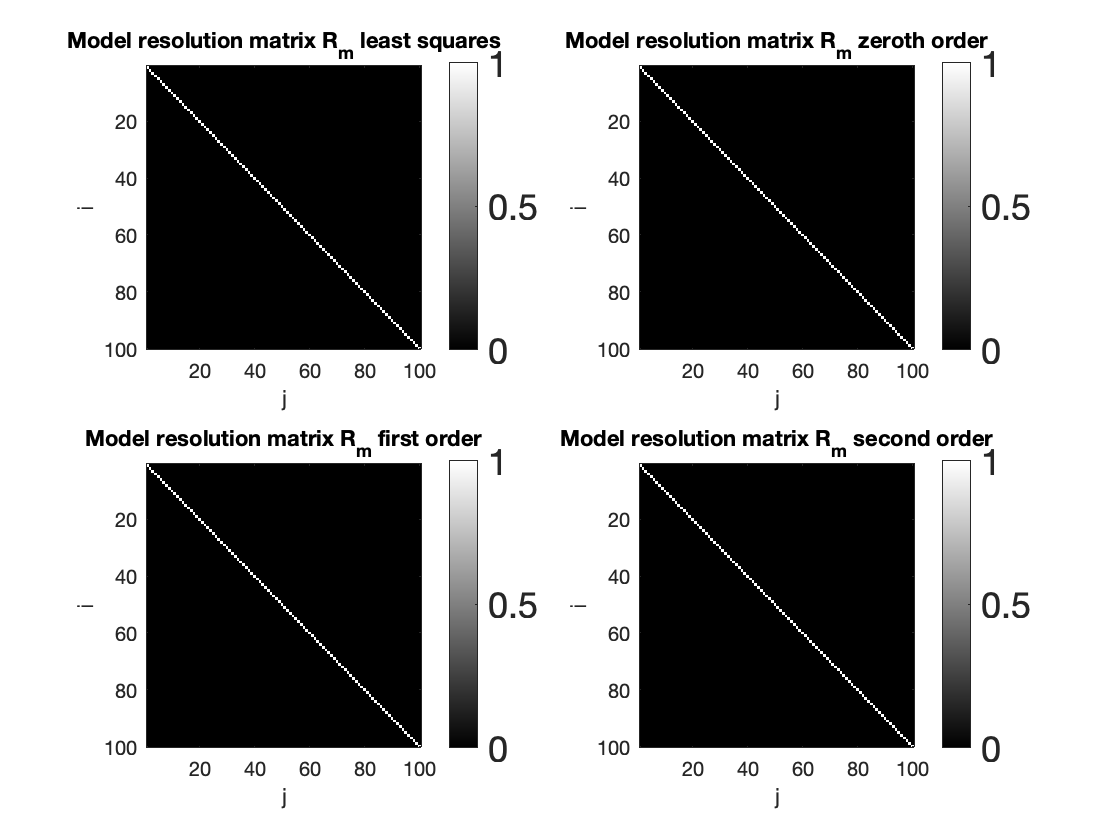

figure(4)
clf
colormap('gray')
subplot(2,2,1)
[U,S,V] = svd(G); p=rank(G);
Vp=V(:,1:p);
Rm=Vp*Vp';
imagesc(Rm)
set(colorbar,'Fontsize',18);
xlabel('j')
ylabel('i')
title('Model resolution matrix R_{m} least squares')

subplot(2,2,2)
[U,S,V] = svd(A); p=rank(A);
Vp=V(:,1:p);
Rm=Vp*Vp';
imagesc(Rm)
set(colorbar,'Fontsize',18);
xlabel('j')
ylabel('i')
title('Model resolution matrix R_{m} zeroth order')

subplot(2,2,3)
[U,S,V] = svd(A1); p=rank(A1);
Vp=V(:,1:p);
Rm=Vp*Vp';
imagesc(Rm)
set(colorbar,'Fontsize',18);
xlabel('j')
ylabel('i')
title('Model resolution matrix R_{m} first order')

subplot(2,2,4)
[U,S,V] = svd(A2); p=rank(A2);
Vp=V(:,1:p);
Rm=Vp*Vp';
imagesc(Rm)
set(colorbar,'Fontsize',18);
xlabel('j')
ylabel('i')
title('Model resolution matrix R_{m} second order')

The model parameter estimates are perfectly resolved, since all the entries on the major diagonal equal to 1 and the rest are zeros, in all the four approaches used.

function [M] = model_parameters(q,U,Lam,Y,k,d,n)
    M = 0;
    for i = n-q+1:n
        M = M + (U(:,i-k)'*d)/(Lam(i))*Y(:,i);
    end
end
